# Heat Diffusion Tutorial

This tutorial will teach you how to set up a steady-state diffusion problem on a membrane using IRACEMA. We will then compare to reference values in the literature.

## Preamble

To make sure everything works fine, we clear the memory and add the IRACEMA scripts to the current path.

clearvars
cd ..
run startup.m
cd UserGuide

## Geometry Definition

The geometry we will be working with is a 0.6m x 1m membrane, as shown in the figure below.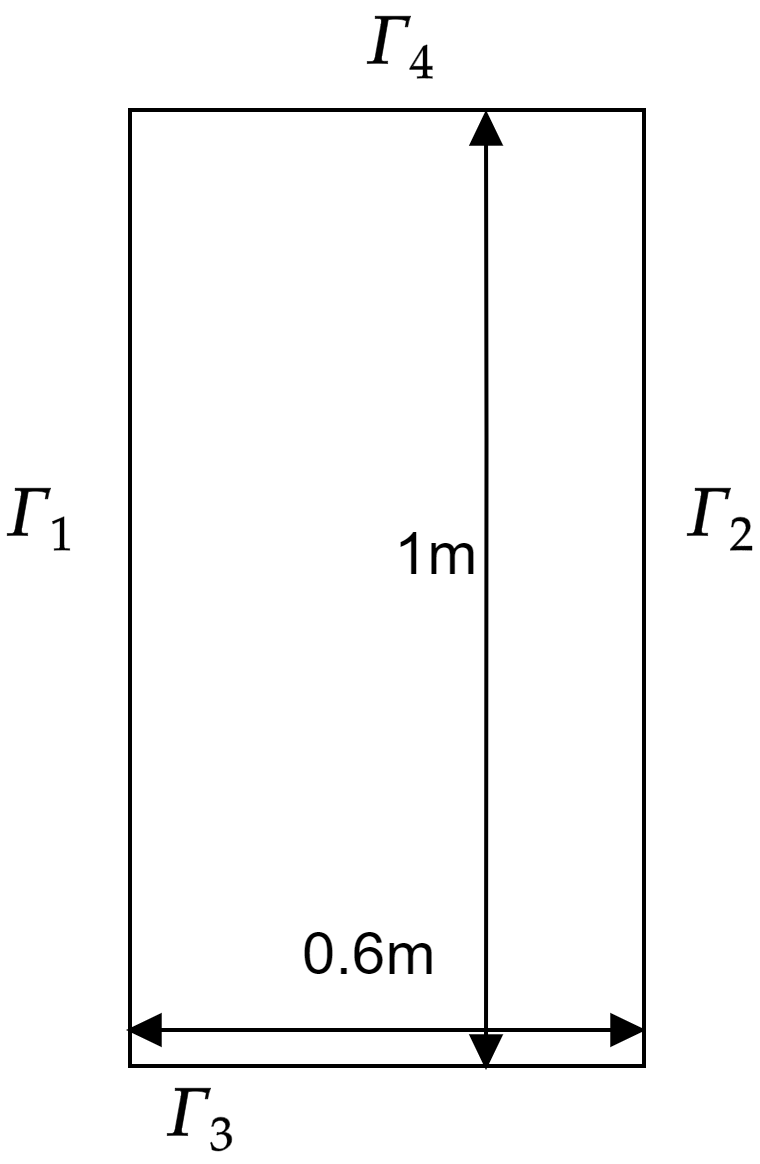The $\Gamma$s represent the boundaries of the model.

The problem we will simulate, have the following Boundary Conditions:

- $\Gamma_1$ is insulated.

- $\Gamma_2$ is convecting to $0^o$C with a heat transfer coefficient of 750 W/(m$\cdot ^o$C)

- $\Gamma_3$ is kept at 100$^o$C

- $\Gamma_4$ is convecting to $0^o$C with a heat transfer coefficient of 750 W/(m$\cdot ^o$C)

And the domain will have thermal conductivity $\alpha = 52$W/(m$\cdot ^o$C).

We begin creating our model by making two lines, and then creating a ruled surface between these lines.

To keep things clean and easy to access, we will make the first parametric direction be related to the x coordinate and the second parametric direction related to the y coordinate. This is something that can be done in linear cases such as lines and rectangles, but be aware that this won't work in more complex geometries.

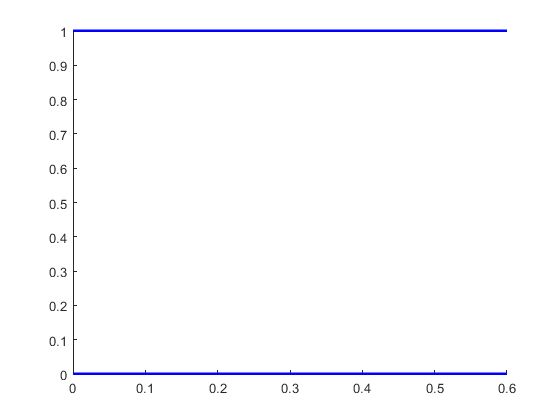

point1 = [0 0 0 1]; % x y z and weight
point2 = [0.6 0 0 1];

Line1 = geo_line(point1, point2);

point3 = [0 1 0 1];
point4 = [0.6 1 0 1];
Line2 = geo_line(point3,point4); %Line2 is the same as Line1, but 1m up in y

figure(1)
Line1.plot_geo
hold on
Line2.plot_geo

With the two lines created, we make a ruled surface between them. We will call this Ruled Surface "Omega", because it will be our function domain.

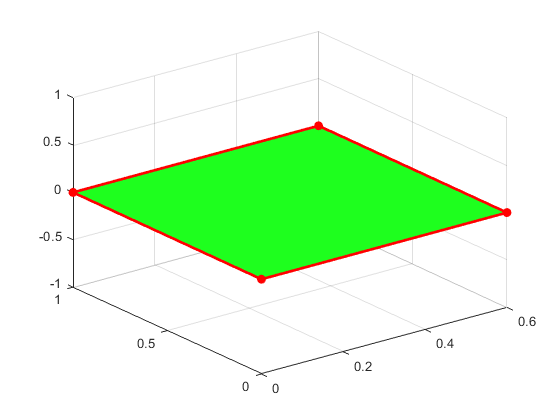

Omega = geo_ruled(Line1,Line2);
figure(2)
Omega.plot_geo('coarse',1,0)

The plot_geo command has the following syntax:

- render can be 'fine', 'coarse' or 'medium' and relates to the amount of points generated to make the picture.

- ControlPointsBoolean is 1 or 0 and relates to the option of showing or not showing the ControlPoints

- IsolinesBoolean is 1 or 0 and relates to the option of showing or not showing the Isolines (element lines)

### *k*-refinement of the Model

We will make the model have 9-by-15 elements, all of polynomial degree 3, so we need to *k*-refine the model.

Omega.DegreeElevate(2,1); % Elevate u-direction by 2 degrees
Omega.DegreeElevate(2,2); % Elevate v-direction by 2 degrees

uKnots = linspace(0,1,30);
uKnots = setdiff(uKnots, [0 1]); % Making it an open interval

vKnots = linspace(0,1,30);
vKnots = setdiff(vKnots,[0 1]);

Omega.KnotRefine(uKnots,1);
Omega.KnotRefine(vKnots,2);

figure(3)
Omega.plot_geo('coarse',0,1) % Showing Isolines -> Element Separation Lines

## Matrix Assemble

For the assembly of poisson type problems, we use the MembraneAssemble function from the IGA toolbox:

For the case of steady-state conduction, the Mass matrix is unecessary, so we build the Stiffness matrix as:

[K,~,ID] = MembraneAssemble(Omega);
alpha = 52; % Heat Diffusivity Coefficient of the Problem
K = alpha*K; % Updating values for the Stiffness Matrix

The ID matrix will be used to plot the solution.

Now, we need to enforce the boundary conditions.

Firstly, we separate our boundary conditions in the three kinds of boundary conditions: Dirichlet, Neumann and Robin.

#### Dirichlet Boundary Conditions

In our problem, $\Gamma_3$ is defined by the Dirichlet Boundary Condition of having a temperature of 100C, or 373.15K. We establish the DOFs that make a Dirichlet Boundary by using the GetBoundaryConditionArray function:

For us to run function, we have to identify the boundary value bval from which parametric direction makes $\Gamma_3$.

With some thought, one can see that $v = 0$ is equivalent to $\Gamma_3$, so we run:

Gamma3 = GetBoundaryConditionArray(Omega,2,0,373.15);

###  Neumann Boundary Conditions

Since the enforcement of Neumann Boundary Conditions must be integrated into the Forcing Vector, we have to identify which elements make the boundary, so for Neumann type boundary conditions, we run the GetBoundaryElements function:

The Neumann boundary, $\Gamma_1$ is defined by $u = 0$, so:

Gamma1Elements = GetBoundaryElements(Omega,1,0,0);

## Robin Boundary Conditions

Robin Boundary Conditions, as Neumann Boundary Conditions, are integrated into the Forcing Vector. They also modify the Stiffness Matrix, so we must have to identify which elements make the boundary. This is done, too, by the GetBoundaryElements function, but with a slight difference.

If we define a Robin Boundary Condition in the form:


$$\nabla u\cdot \overrightarrow{n} =r-\beta u$$


we run the GetBoundaryElements as:

For both our remaining boundaries, $\Gamma_2$ and $\Gamma_4$, we have:

$h = -750 W/mC$, $T_\infty = 273.15$K

Solving the heat equation robin condition for $r$ and $\beta$, we have that:

$r=\frac{-{\textrm{hT}}_{\infty } }{\alpha }$; $\beta = \frac{-h}{\alpha}$.

So we build that into our Gammas:

h = -750;
T_inf = 273.15; % Zero Celsius, in Kelvin
ROBIN = -h*T_inf/alpha;
BETA = -h/alpha;
Gamma2Elements = GetBoundaryElements(Omega,1,1,[ROBIN,BETA]);
Gamma4Elements = GetBoundaryElements(Omega,2,1,[ROBIN,BETA]);

### Enforcement of Natural and Mixed Boundary Conditions

We must now integrate the Neumann and Robin Boundary Conditions into our Stiffness and Force Arrays. Since we haven't created yet a force array, we will declare it now:

F = zeros(length(K),1);

Integration of the Neumann and Robin Conditions are as simples as calling a function. First, we will combine the Robin Boundary Elements into one unique array:

RobinElements = [Gamma2Elements; Gamma4Elements];

Then we change a little the names around:

NeumannElements = Gamma1Elements;

And we are ready to apply the integration of boundary conditions:

[K,F] = RobinBC(Omega,K,F,RobinElements);
[~,F] = RobinBC(Omega,K,F,NeumannElements);

They are done using the same function!

All that's left now is the solving of the system and the enforcement of Dirichlet Boundary Conditions.

## Enforcement of Essential Boundary Conditions

This is done through a function, much like Natural and Mixed Boundary Conditions

So:

[d,~] = DirichletBC(K,F,Gamma3);

## Plotting the Solution

We simply run

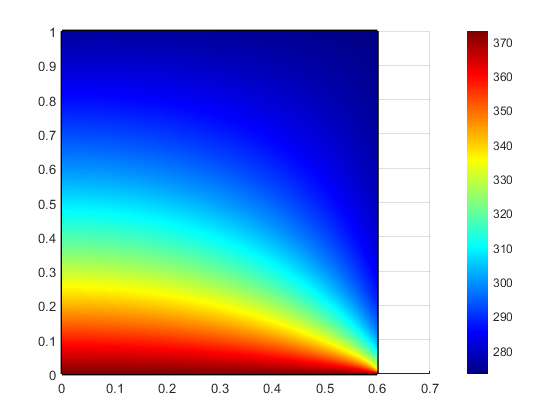

PlotDisplacement(d,ID,Omega);
caxis([273.15 373.15])
view([-0.96 90.00])

To check the convergence value at x = 0.6m, y = 0.2m, we do a little trick by letting d be the z of a plate using the Mode Visualization function:

MM = VisualizeModes(Omega,d,ID);
Convergence = MM{1}.eval_point(1,0.2);
str = 'Temperatue at x = 0.6m, y = 0.2m:';
str2 = num2str(Convergence.z - 273.15, '%.2f');
a = strcat({str},{' '},{str2},{'C'});
display(a{1});

Temperatue at x = 0.6m, y = 0.2m: 16.64C


The benchmark result for target location is a temperature of 18.25C.